# Rat Reunion Part 2: Stranger vs. Cagemate

## 0. Indices

rr_rats = intersect(intersect(ya_ind, rat_ind), rr_ind); %only using the young adults
[u_pairs, ia_r, ic_r] = unique(rdb.paircode(rr_rats));

%strangers and cagemates
ostrangers_rr = find(ismember(rr_rats(ia_r), ostr_ind));
cagemates_rr = find(ismember(rr_rats(ia_r), cag_ind));
nstrangers_rr = find(ismember(rr_rats(ia_r), nstr_ind));

num_ostr = length(ostrangers_rr);
num_cagm = length(cagemates_rr);
num_nstr = length(nstrangers_rr);

%

parfind = cell(length(u_pairs),1);
 for i = 1:length(u_pairs)
     parfind{i} = intersect(find(rdb.paircode == u_pairs(i)), rr_rats);
 end


betypes = [-1 1 2 3 5 4];
 behaves2use = 1:5;
  behaviortypes = {'wrestling' 'mounting' 'grooming' 'rear-sniffing' 'face-to-face' 'body-sniffing' 'huddling'};
 phystypes = betypes; %might have used wrong variable name so this is just a catch 
 


## I. Physical interactions, total time

### A.1 Physical interactions, combined -- create matrix

 maxexposurenum = 9;

    septime_mat = nan(length(u_pairs), maxexposurenum, length(betypes));
    septime_new = nan(length(u_pairs), maxexposurenum, length(betypes_n));
        for i = 1:size(u_pairs,1)
            for j = 1:maxexposurenum
                curind = intersect(parfind{i}, find(rdb.exposurenum == j));
                if ~isempty(curind)
                    if rdb.stranger(curind) < 2 | rdb.stranger(curind) == 4
                        septime_mat(i,j,1:length(betypes)) = sumbehav(curind,:);
                        septime_new(i,j,1:length(betypes_n)) = sumbehav_new(curind,:);
                    elseif rdb.stranger(curind) == 2 % placing 24hr new cagemates in pos 6 (if 2, will just overwrite... shouldn't be 2)
                        septime_mat(i,6,1:length(betypes)) = sumbehav(curind,:);
                        septime_new(i,6,1:length(betypes_n)) = sumbehav_new(curind,:);
                    elseif rdb.stranger(curind) == 3 % placing 1 week new cagemate in pos 8 (if 2, will just overwrite, shouldn't be 2)
                        septime_mat(i,8,1:length(betypes)) = sumbehav(curind,:);
                        septime_new(i,8,1:length(betypes_n)) = sumbehav_new(curind,:);
                    end
                end
            end
        end

        septime_new = cat(3, septime_new, septime_mat(:,:,2:end));



### A.2.a Figure & Stats for combined -- start with Day 1 only

 stm_all = nansum(septime_mat(:,:,behaves2use),3);
 stm_all(stm_all == 0) = nan;
 
% not normalized:
f = figure

f =   Figure (16) with properties:

      Number: 16
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [573 544 560 420]
       Units: 'pixels'

  Show all properties


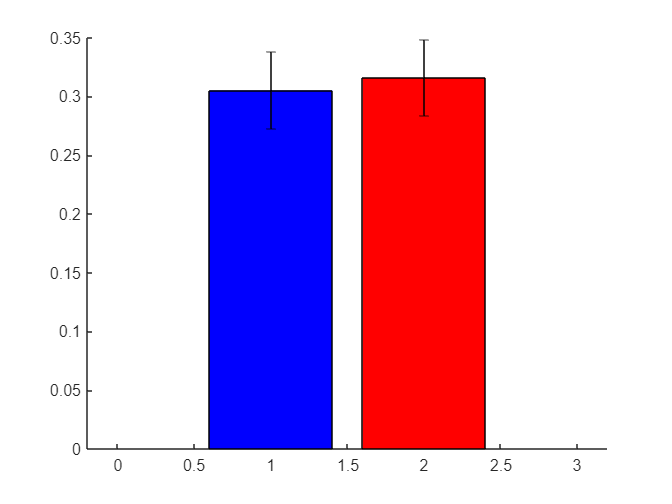

    hold on
%    f2A = subplot(1,2,);
    bar(1, nanmean(stm_all(cagemates_rr,1)) , 'FaceColor', 'b');
    errorbar(1, nanmean(stm_all(cagemates_rr,1)), std(stm_all(cagemates_rr,1)/sqrt(num_cagm)), 'k');

    bar(2, nanmean(stm_all(ostrangers_rr,1)) , 'FaceColor', 'r');
    errorbar(2, nanmean(stm_all(ostrangers_rr,1)), std(stm_all(ostrangers_rr,1)/sqrt(num_cagm)), 'k');

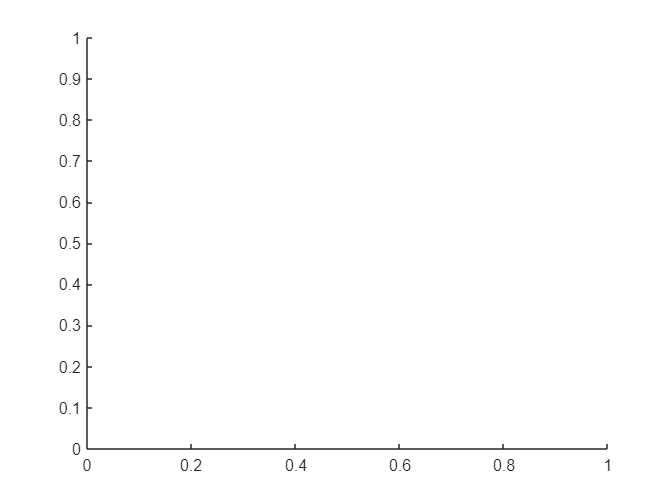


 
    f2A = get(figure, 'Children');
   
xticklabels = {'cagemate', 'stranger'};


%    eb = errorbar(1:3, nanmean(stm_all), nanstd(stm_all)/sqrt(size(septime_mat,1)-1), 'LineStyle', 'none', 'Color', [.5 .5 .5]);
%set()
%set(f2A, 'XTickLabel', xticklabels);
%    set(get(f2A, 'XLabel'), 'String', 'condition');
%    set(get(f2A, 'YLabel'), 'String', 'proportion of time');
%    set(get(f2A, 'Title'), 'String', 'All Physical Interactions');
    box off

### B 1.a Figure & Stats for combined -- start with Day 1 only

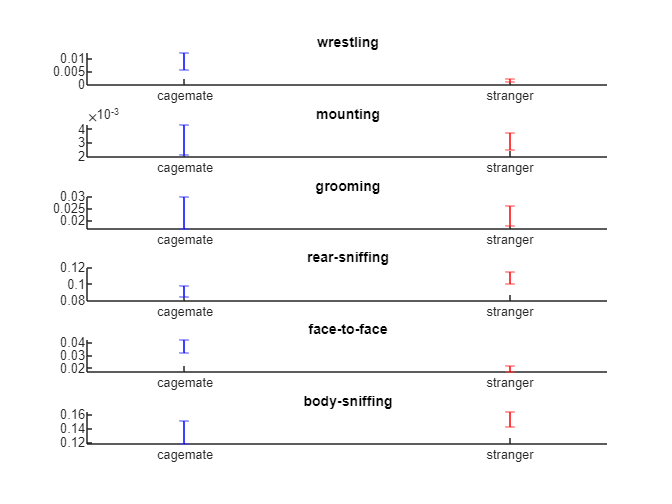

 behaves2use = 1:6;

figure
 for i = 1:length(behaves2use)
%     f2B = subplot(4,3,i*3);
    f2B = subplot(length(behaves2use),1,i);
     %bar(1:3, nanmean(septime_mat(:,:,i)));
     hold on
     e_sub = errorbar(1, nanmean(septime_new(cagemates_rr,1,i)), nanstd(septime_new(cagemates_rr,1,i))/sqrt(size(septime_new,1)-1), 'b'); %'LineStyle', 'none');
     e_sub = errorbar(2, nanmean(septime_new(ostrangers_rr,1,i)), nanstd(septime_new(ostrangers_rr,1,i))/sqrt(size(septime_new,1)-1), 'r'); %'LineStyle', 'none');
%    ax = gca;
%    ax.Clipping = 'off';
    set(f2B, 'XTick', [1:2]);
     set(f2B, 'XTickLabel', xticklabels);
  %  set(get(f1B, 'XLabel'), 'String', 'condition');
 %   set(get(f1B, 'YLabel'), 'String', 'proportion of time');
    set(get(f2B, 'Title'), 'String', behaviortypes{i});
    set(get(e_sub, 'Parent'), 'XLim', [.7 2.3]);
     box off
 end